env= rlPredefinedEnv("BasicGridWorld")

env =   rlMDPEnv with properties:

       Model: [1×1 rl.env.GridWorld]
    ResetFcn: []


env.Model

ans =   GridWorld with properties:

                GridSize: [5 5]
            CurrentState: "[1,1]"
                  States: [25×1 string]
                 Actions: [4×1 string]
                       T: [25×25×4 double]
                       R: [25×25×4 double]
          ObstacleStates: [4×1 string]
          TerminalStates: "[5,5]"
    ProbabilityTolerance: 8.8818e-16


env.Model.R

ans = ans(:,:,1) =

    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1  

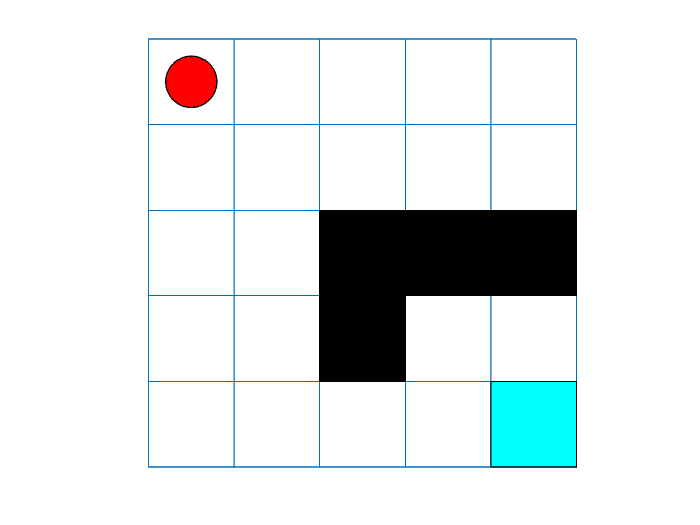

plot(env)




env.ResetFcn = @() 21

env =   rlMDPEnv with properties:

       Model: [1×1 rl.env.GridWorld]
    ResetFcn: @()21


env.ResetFcn

ans = function_handle with value:
    @()21


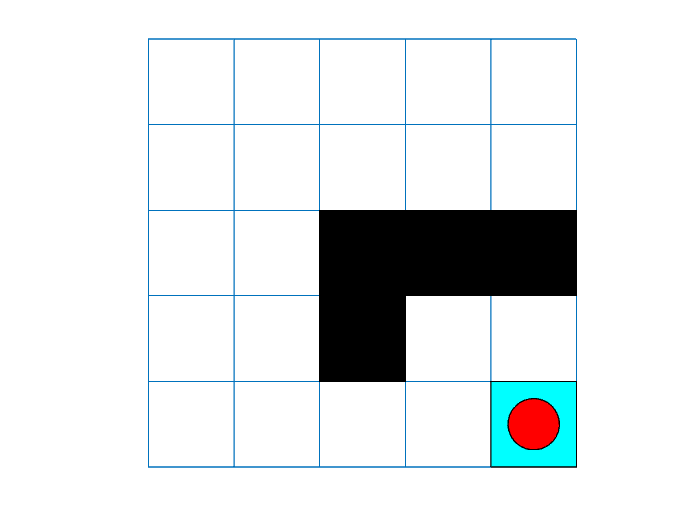

qTable = rlTable(getObservationInfo(env), ...
    getActionInfo(env));
qFcnAppx = rlQValueFunction(qTable, ...
    getObservationInfo(env), ...
    getActionInfo(env));
qAgent = rlQAgent(qFcnAppx);
qAgent.AgentOptions.EpsilonGreedyExploration.Epsilon = .4;
qAgent.AgentOptions.CriticOptimizerOptions.LearnRate = 0.01;
trainOpts = rlTrainingOptions;
trainOpts.MaxStepsPerEpisode = 50;
trainOpts.MaxEpisodes= 50;
trainOpts.StopTrainingCriteria = "AverageReward";
trainOpts.StopTrainingValue = 11;
trainOpts.ScoreAveragingWindowLength = 30;
trainingStats = train(qAgent,env,trainOpts);

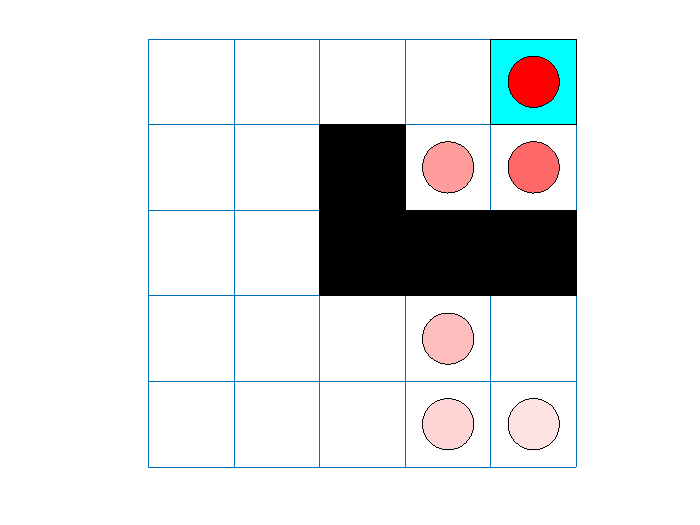

plot(env)
set(gca, 'YDir','reverse')
env.Model.Viewer.ShowTrace = true;
env.Model.Viewer.clearTrace;
sim(qAgent,env)


%Megvagy te geci

x = [];
y = [];

for i = 1:size(exp.Observation.MDPObservations.Data,3)
    data = exp.Observation.MDPObservations.Data(i);
    state = env.Model.States(data);
    matrix = str2num(state);
    x = [x;matrix(:,2)];
    y = [y;matrix(:,1)];
end

x

x =      5
     4
     4
     4
     5
     5


y

y =      1
     1
     2
     4
     4
     5


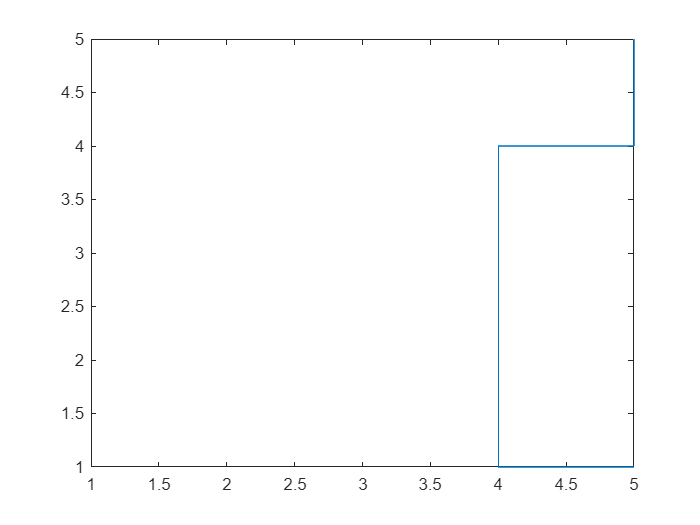

figure
plot(x,y)
axis([1 5 1 5])



size(exp.Observation.MDPObservations.Data,3)

ans = 6


teszt = exp.Observation.MDPObservations.Data(1)

teszt = 21

teszt2  = exp.Observation.MDPObservations.Data(2)

teszt2 = 16

state = env.Model.States(teszt)

state = "[1,5]"

state2 = env.Model.States(teszt2)

state2 = "[1,4]"

X = str2num(state)

X =      1     5


Y = str2num(state2)

Y =      1     4


New = [X; Y]

New =      1     5
     1     4


x = New(:,2)

x =      5
     4


y = New(:,1) 

y =      1
     1


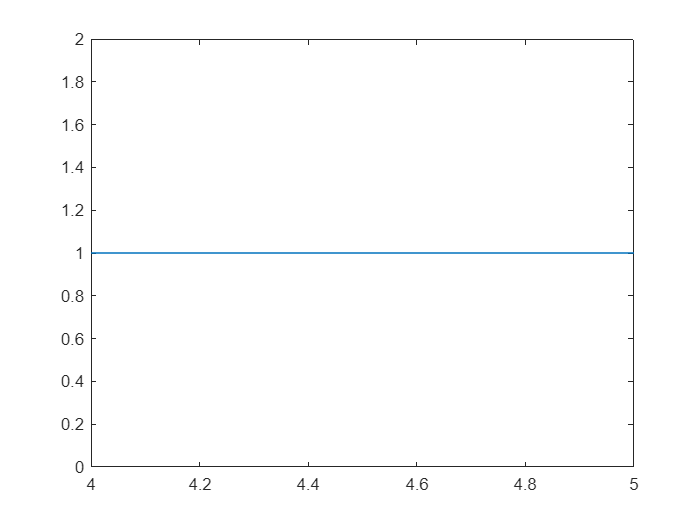

figure
plot(x,y)